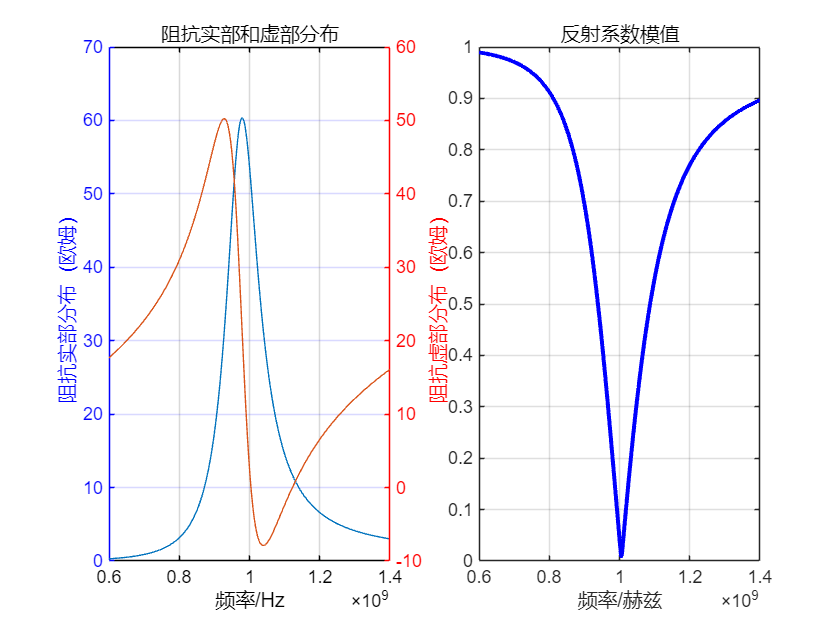

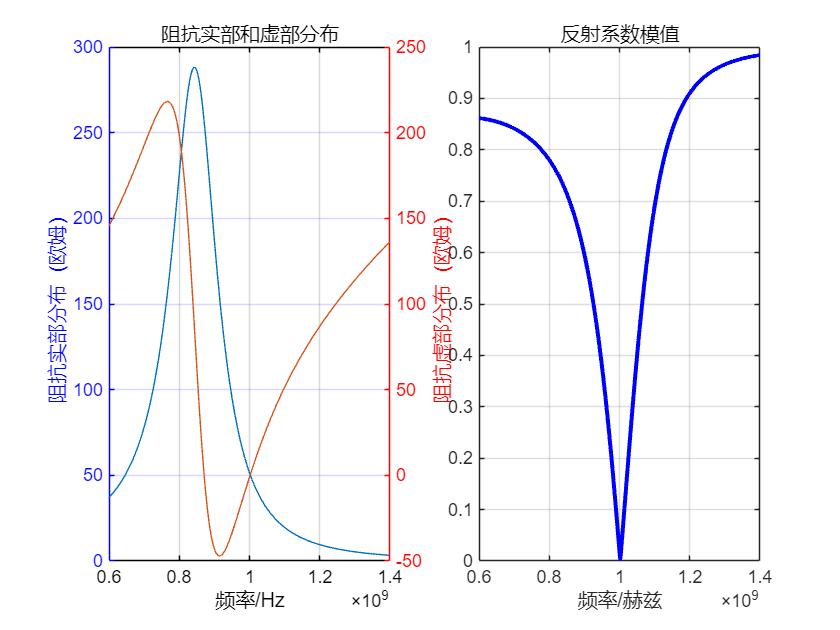

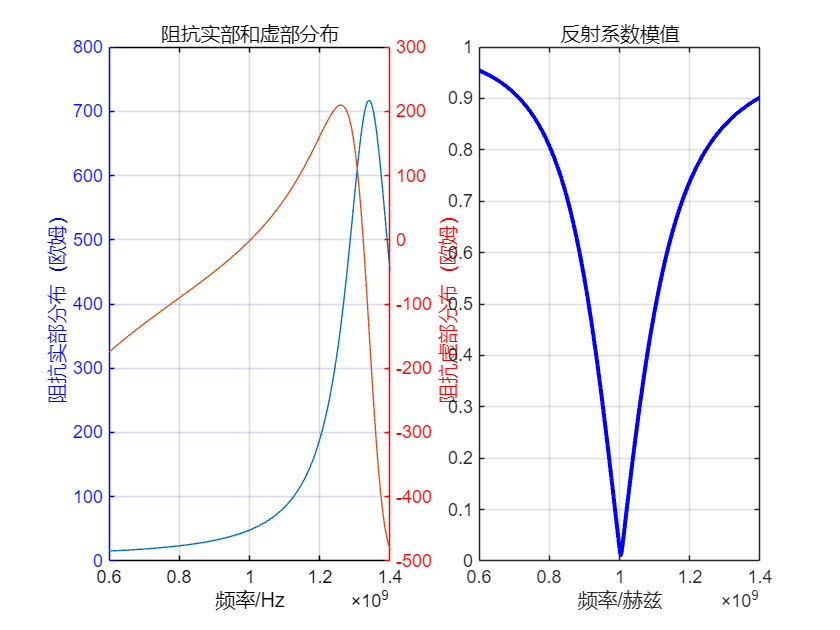

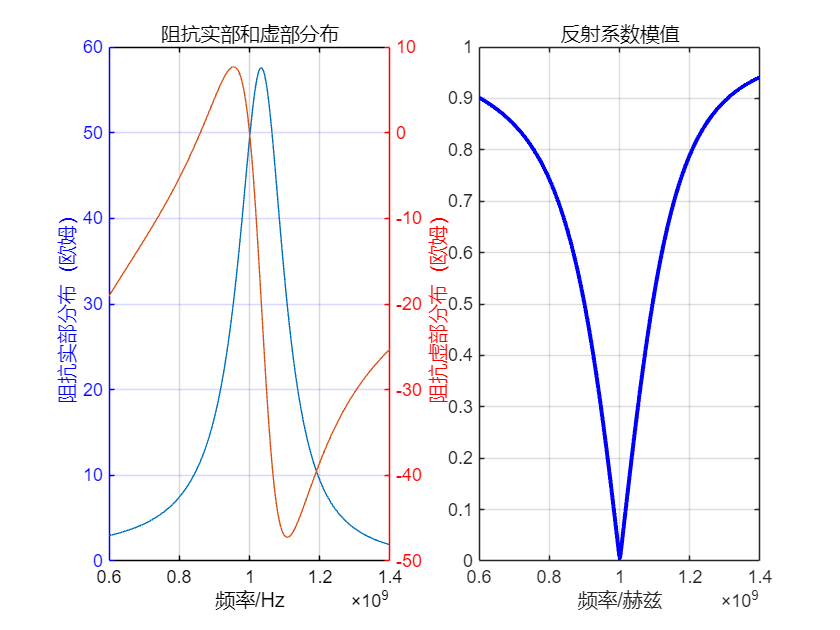



clear;

Z0=50;                          
Rl=10;                          
Ll=1e-8;                        
fmin=6e8;                       
fstep=1e6;                      
fmax=1.4e9;                     
f0=(fmin+fmax)/2;               
f=fmin:fstep:fmax;              
Zl0=Rl+1i*2*pi*f0*Ll;           
Zl=Rl+1i*2*pi*f*Ll;             


C1=1.9e-12;
L1=4e-9;
Zin1_1=ser_cap(C1,f,Zl);
Zin1=par_ind(L1,f,Zin1_1);
T1=(Zin1-Z0)./(Zin1+Z0);


C2=3.5E-12;
L2=21.3e-9;
Zin2_1=par_cap(C2,f,Zl);
Zin2=ser_ind(L2,f,Zin2_1);
T2=(Zin2-Z0)./(Zin2+Z0);


C3_1=1.4e-12;
C3_2=1.2e-12;
Zin3_1=par_cap(C3_1,f,Zl);
Zin3=ser_cap(C3_2,f,Zin3_1);
T3=(Zin3-Z0)./(Zin3+Z0);


C4_1=3.7e-12;
C4_2=6.4e-12;
Zin4_1=ser_cap(C4_1,f,Zl);
Zin4=par_cap(C4_2,f,Zin4_1);
T4=(Zin4-Z0)./(Zin4+Z0);



Zin=[Zin1;Zin2;Zin3;Zin4];
T=[T1;T2;T3;T4];
for k=1:4
    figure(k);
    subplot(1,2,1);
    Real_and_imag_of_impedance(Zin(k,:),f);
    subplot(1,2,2);
    reflection_coefficient(T(k,:),f);
end


function [Zin]=ser_ind(L,f,Zl)
    Zin=Zl+2*pi*f*L*1j;
end

function [Zin]=ser_cap(C,f,Zl)
    Zin=Zl-1j./(2*pi*f*C);
end

function [Zin]=par_cap(C,f,Zl)
    Zin=1./(1./Zl+1j*2*pi*f*C);
end

function [Zin]=par_ind(L,f,Zl)
    Zin=1./(1./Zl-1j./(2*pi*f*L));
end

function Real_and_imag_of_impedance(Zin,f)
    AX=plotyy(f,real(Zin),f,imag(Zin));
    set(AX(1),'Xcolor','k','Ycolor','b');              
    set(AX(2),'Xcolor','k','Ycolor','r');              
    set(get(AX(1),'Ylabel'),'string','阻抗实部分布（欧姆）');
    set(get(AX(2),'Ylabel'),'string','阻抗虚部分布（欧姆）');
    title('阻抗实部和虚部分布');
    xlabel('频率/Hz');
    grid on;
end

function reflection_coefficient(T,f)
    plot(f,abs(T),'b','LineWidth', 2); 
    title('反射系数模值');
    xlabel('频率/赫兹');
    grid on;
end